## Analysis Pipeline for PEP WP-4 EEG Project

### House keeping

clc; clear; close all;%dbstop if error;
cfg = struct;
d = struct;

% add functions folder to path
cfg.functionPath = fullfile(pwd,'utilities');
addpath(genpath(cfg.functionPath))

### Define to-be-analyzed subjects

%cfg.subNums = [101:103, 105:106, 108:117, 119:122, 124, 126:130, 133]; % 118 did not finish the experiment, 140, 114
cfg.subNums = [101:103, 105:106, 108:117, 119:122, 124, 126:131, 133, 141:142]; % 104
cfg = defaultCfg(cfg);

### Preprocessing

disp(['Running pre-processing...' newline]);

Running pre-processing...



preprocess_EEG(cfg);

Pre-processed data for sub-101 exist already

Pre-processed data for sub-102 exist already

Pre-processed data for sub-103 exist already

Pre-processed data for sub-105 exist already

Pre-processed data for sub-106 exist already

Pre-processed data for sub-108 exist already

Pre-processed data for sub-109 exist already

Pre-processed data for sub-110 exist already

Pre-processed data for sub-111 exist already

Pre-processed data for sub-112 exist already

Pre-processed data for sub-113 exist already

Pre-processed data for sub-114 exist already

Pre-processed data for sub-115 exist already

Pre-processed data for sub-116 exist already

Pre-processed data for sub-117 exist already

Pre-processed data for sub-119 exist already

Pre-processed data for sub-120 exist already

Pre-processed data for sub-121 exist already

Pre-processed data for sub-122 exist already

Pre-processed data for sub-124 exist already

Pre-processed data for sub-126 exist already

Pre-processed data for sub-127 exi

### Category decoding

disp(['Running decoding...' newline]);

Running decoding...



%decoding_EEG(cfg);

### Individual decoding accuracies

disp(['Running individual decoding...' newline]);

Running individual decoding...



%individual_decoding_accuracies(cfg);

### Pairwise decoding

cfg.plotting = false;
cfg.plot_rdm = false;
cfg.pca = false;
cfg.nTrials2average = 1;
disp(['Running pairwise decoding...' newline]);

Running pairwise decoding...



[d.pairRep, d.meanAcc, cfg] = PairwiseTPLDAclassifier(cfg);

RDM for sub-101 already exists
RDM for sub-102 already exists
RDM for sub-103 already exists
RDM for sub-105 already exists
RDM for sub-106 already exists
RDM for sub-108 already exists
RDM for sub-109 already exists
RDM for sub-110 already exists
RDM for sub-111 already exists
RDM for sub-112 already exists
RDM for sub-113 already exists
RDM for sub-114 already exists
RDM for sub-115 already exists
RDM for sub-116 already exists
RDM for sub-117 already exists
RDM for sub-119 already exists
RDM for sub-120 already exists
RDM for sub-121 already exists
RDM for sub-122 already exists
RDM for sub-124 already exists
RDM for sub-126 already exists
RDM for sub-127 already exists
RDM for sub-128 already exists
RDM for sub-129 already exists
RDM for sub-130 already exists
RDM for sub-131 already exists
RDM for sub-133 already exists
RDM for sub-141 already exists
RDM for sub-142 already exists


### **t-test**

cfg.plotting = true;
cfg.alpha = 0.01;
cfg.xlim = [-0.02, 0.5];
disp(['Running t-test on pairwise decoding accuracies...' newline]);

Running t-test on pairwise decoding accuracies...



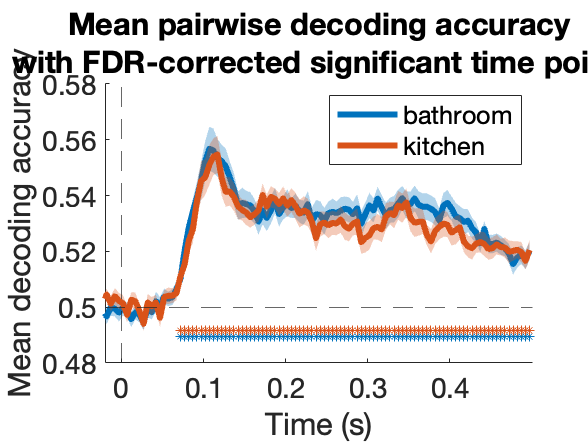

stats_ttest(cfg, d);

### ISC of representation

cfg.plotting = true;
cfg.plot_rdm = false;
cfg.regressOutMean = false;
cfg.dissimilarity = true;
cfg.ISC_types = {'pairRep'};
cfg.correlation_type = 'Spearman';
disp(['Running ISC...' newline]);
d = getISCofRespresentation(cfg, d);

### ISC of representation with regressOutMean

cfg.plotting = true;
cfg.plot_rdm = false;
cfg.regressOutMean = true;
cfg.dissimilarity = true;
cfg.ISC_types = {'pairRep'};
cfg.correlation_type = 'Spearman';
cfg.new_figure = false;
disp(['Running ISC...' newline]);

Running ISC...



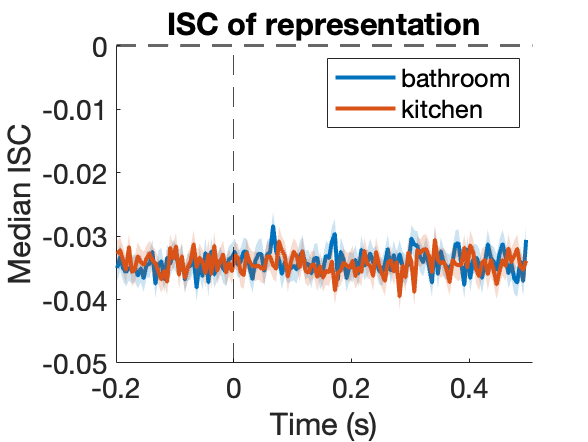

d = getISCofRespresentation(cfg, d);

### Get inter-subject similarity on drawings

cfg.dnn = 'vgg16_imagenet';
cfg.layer_type = 'late';
%cfg.layer_type = 'early_mid';
cfg.correlation_type = 'Spearman';
cfg.dissimilarity = true;
cfg.plot_rdm = false;
cfg.MaxColorValue = 1;
cfg.new_figure = true;

% Create output directory if wanted
output_dir = fullfile(pwd, '..', 'dnn_features');
if exist(output_dir, 'dir')
    rmdir(output_dir, 's');
end

% get images
cfg.analysis_names = {'typical', 'control', 'photos'};
images = load_images(cfg);

Loaded image: 101_bat_gen1.png
Loaded image: 101_bat_gen2.png
Loaded image: 101_bat_gen3.png
Loaded image: 102_bat_gen1.png
Loaded image: 102_bat_gen2.png
Loaded image: 102_bat_gen3.png
Loaded image: 103_bat_gen1.png
Loaded image: 103_bat_gen2.png
Loaded image: 103_bat_gen3.png
Loaded image: 104_bat_gen1.png
Loaded image: 104_bat_gen2.png
Loaded image: 104_bat_gen3.png
Loaded image: 105_bat_gen1.png
Loaded image: 105_bat_gen2.png
Loaded image: 105_bat_gen3.png
Loaded image: 106_bat_gen1.png
Loaded image: 106_bat_gen2.png
Loaded image: 106_bat_gen3.png
Loaded image: 108_bat_gen1.png
Loaded image: 108_bat_gen2.png
Loaded image: 108_bat_gen3.png
Loaded image: 109_bat_gen1.png
Loaded image: 109_bat_gen2.png
Loaded image: 109_bat_gen3.png
Loaded image: 110_bat_gen1.png
Loaded image: 110_bat_gen2.png
Loaded image: 110_bat_gen3.png
Loaded image: 111_bat_gen1.png
Loaded image: 111_bat_gen2.png
Loaded image: 111_bat_gen3.png
Loaded image: 112_bat_gen1.png
Loaded image: 112_bat_gen2.png
Loaded i

% layer similiarity
[d, cfg] = get_dnn_layer_similarity(d, images, cfg); % in the function cfg.regressOutMean = false!

analysis typical - layer #1 - category: bathroom
analysis control - layer #1 - category: bathroom
analysis photos - layer #1 - category: bathroom
analysis typical - layer #1 - category: kitchen
analysis control - layer #1 - category: kitchen
analysis photos - layer #1 - category: kitchen


% filter for included subjects
d = filterCurrentSubs(d, cfg);

### Compare ISC from drawings with ISC of neural representations 

 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated


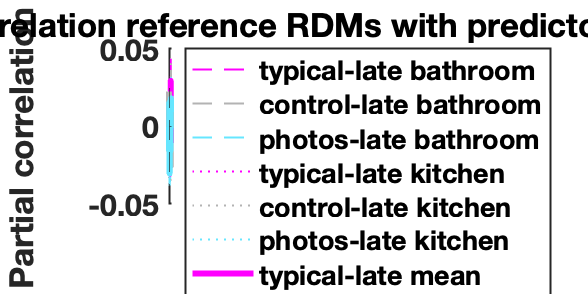

% preparation
cfg.partial_cor = true;
cfg.plotting = true;
cfg.predictor_RDMs = {'typical_late', 'control_late', 'photos_late'};
% cfg.predictor_RDMs = {'typical_early', 'control_early', 'photos_early'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
cfg.dnns = {'vgg16_imagenet'};
cfg.show_single_cate = true;
cfg.partial_correlation_type = 'Pearson';
cfg.smoothing_window = 10;
% run
d = compare_tp_RDMs_to_predictor_RDMs(d, cfg);

### Permutation test

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evalu

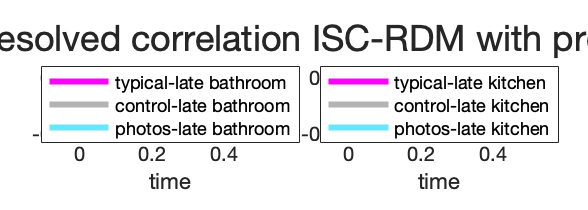

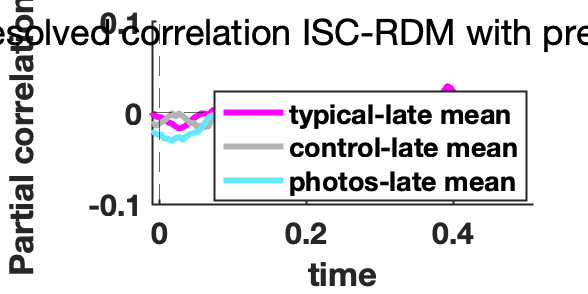

cfg.n_permutations = 10000;
cfg.alpha = 0.05;
cfg.cluster = true;
cfg.FDR = true;
cfg.min_cluster_size = 3;
d.stats = stats_permutationtest(cfg,d);

### Plot significant time points

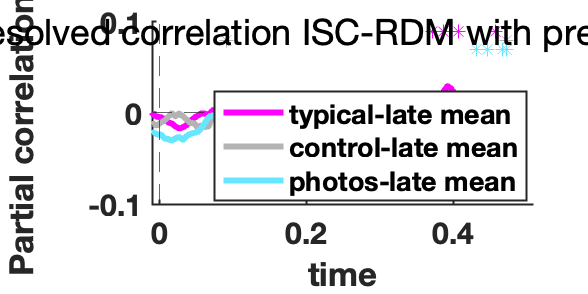

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evalu

plot_corr_sig(cfg, d, d.stats.pvalMat.onesided, 'uncor');
if cfg.FDR

    plot_corr_sig(cfg, d, d.stats.pvalMat.onesided.FDR, 'FDR');
end

if cfg.cluster
    plot_corr_sig(cfg, d, d.stats2, 'cluster');
end

### Behavioral data

d.beh = beh_task(cfg);

### Stimuli RDM

cfg.dnns = {'vgg16_imagenet'};
% cfg.layer_type = 'late';
cfg.layer_type = 'early_mid_late';
cfg.correlation_type = 'Spearman';
cfg.plot_rdm = false;
cfg.new_figure = true;
cfg.analysis_names = {'stimuli'};
cfg.exp_num = 2;

% Create output directory if wanted
output_dir = fullfile(pwd, '..', 'dnn_features', 'stimuli');
if exist(output_dir, 'dir')
    rmdir(output_dir, 's');
end

if ~exist('images','var')
    images = struct;
end

% cfg.layer_names = {'early', 'mid', 'late'};
cfg.predictor_RDMs = {'stimuli_early', 'stimuli_mid', 'stimuli_late'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
[cfg, d, images] = make_RDM_for_stimuli(cfg, d, images);

### Compare stimuli RDM with pairwise decoding

cfg.save_name = 'compare_tp_RDMs_to_stimuli_RDM'
d.stimuli = compare_pairwiseDecodingRDM_with_stimuliRDM(cfg, d);

### t-test

cfg.plotting = true;
cfg.smoothing_window = 5;
cfg.alpha = 0.05;
stats_ttest_stimuli(cfg,d);

End Message

% finished!
disp([ ...
    newline, ...
    '#########################', ...
    newline, ...
    '####### ALL DONE! #######', ...
    newline, ...
    '#########################', ...
    newline ...
    ]);